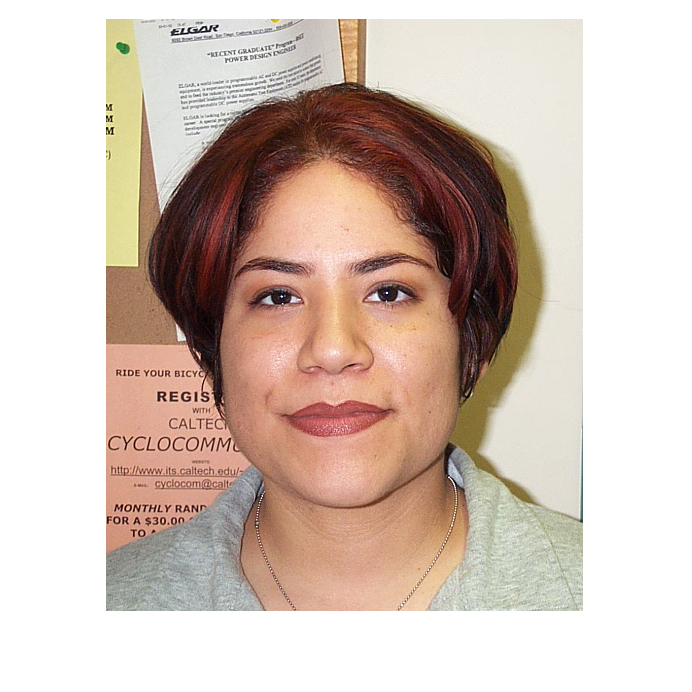

C1 = imread('../TNM034/Facial-recognition/db/DB0/db0_1.jpg');
imshow(C1)

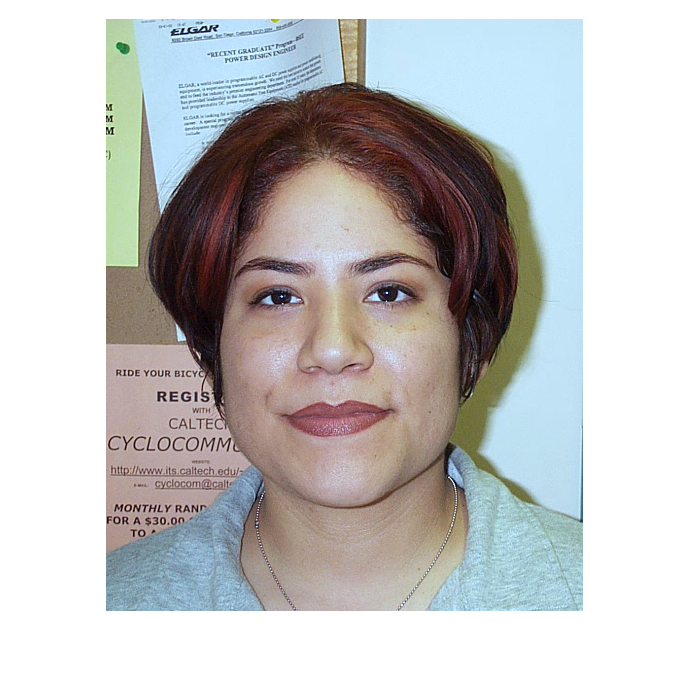


% Dela upp färgkanalerna
r = C1(:,:,1); % Röd kanal
g = C1(:,:,2); % Grön kanal
b = C1(:,:,3); % Blå kanal

r_avg = mean2(r); 
g_avg = mean2(g); 
b_avg = mean2(b); 

% Beräkna faktorer för att balansera kanalerna
alfa = g_avg/r_avg;
beta = g_avg/b_avg;

% Justera färgkanalerna med faktorerna
r_sensor = alfa.*r;
g_sensor = g;
b_sensor = beta.*b;

% Visa den justerade bilden
greyworld_img = cat(3, r_sensor, g_sensor, b_sensor);
imshow(greyworld_img)

imwrite(greyworld_img,'../TNM034/Facial-recognition/facedetection/grayworld.png')

